% Variables globales
global  alpha beta phi rss s0 rst tht chi tau T

alpha = 0.3;
beta = 0.95;
phi = 0.5;
rss = (1/beta)-1;
s0 = 0;        % Activos internacionales iniciales
th0 = 10;       % Productividad inicial
T = 100;         % Número de períodos
tau = 0.06;
                              
%% Solución estado estacionario
% Consumo
css   = (th0/(1+phi))+(1/(1+phi))*((1-beta)/beta)*s0;
% Capital domestico
kdss = ((((alpha*phi*th0)/(1+rss))^(1/(1-alpha)))*((((1-phi)*(1-tau))/phi))^(((alpha*(1-phi))/(1-alpha)))) ;
% Cpital extranjero
kxss = ((((alpha*phi*th0)/(1+rss))^(1/(1-alpha)))*((((1-phi)*(1-tau))/phi))^(((1-alpha*phi)/(1-alpha)))) ; 
% Producción
yss = th0*((kdss^phi)*(kxss^(1-phi))^alpha);
% Cuenta Corriente
cass  = 0;

%% I) Aumento temporal en productividad
% Variables rst y tht
rst = rss*ones(T,1);
tht = th0*ones(T,1);

% Creamos el choque temporal en productividad
thprime = 15;
tht(1) = thprime;
for i = 1:50
    tht(i+1)=th0+0.88*(tht(i)-th0);
end

% Proponemos un punto inicial
x0 = ones(1,T)'*[css;kdss;kxss;yss;cass;s0]';

% Resolvemos el equilibrio
F = fsolve(@ftrans,x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


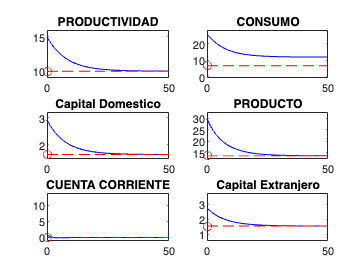


wt  = F(:,1);
lt  = F(:,2);
yt  = F(:,3);
cat = F(:,4);
st  = F(:,5);
ct = F(:,6);

% Graficamos las trayectorias de la productividad, consumo, trabajo, 
% producción, cuenta corriente, y activos de la economía.
figure(1)

subplot(3,2,1)
plot((1:51)-1,tht(1:51),'b-',0,th0,'ro',(1:51)-1,th0*ones(51,1),'r--')
axis ([0, 50, min(tht) - 1, max(tht) + 1]) % Graficas primero sin ejes y explicar cómo escogerlos
title('PRODUCTIVIDAD')

subplot(3,2,2)
plot((1:51)-1,ct(1:51),'b-',0,css,'ro',(1:51)-1,css*ones(51,1),'r--')
axis ([0, 50, min(min(ct), min(css))*0.9, max(max(ct), max(css))*1.1]) % Explicar porque necesitamos el min/max(min/max(ct, css))
title('CONSUMO')

subplot(3,2,3)
plot((1:51)-1,wt(1:51),'b-',0,kdss,'ro',(1:51)-1,kdss*ones(51,1),'r--')
axis ([0, 50, min(min(wt), min(kdss))*0.9, max(max(wt), max(kdss))*1.1]) % Explicar porque aquí -1 y +1 pueden no ser ideales
title('Capital Domestico')

subplot(3,2,4)
plot((1:51)-1,yt(1:51),'b-',0,yss,'ro',(1:51)-1,yss*ones(51,1),'r--')
axis ([0, 50, min(min(yt), min(yss))*0.9, max(max(yt), max(yss))*1.1]) 
title('PRODUCTO')

subplot(3,2,5)
plot((1:51)-1,cat(1:51),'b-',0,cass,'ro',(1:51)-1,cass*ones(51,1),'r--')
axis ([0, 50, min(min(cat), min(cass)) - 1, max(max(cat), max(cass)) + 1]) % Explicar que conviene más el -1 y +1 porque CAss = 0
title('CUENTA CORRIENTE')

subplot(3,2,6)
plot((1:51)-1,lt(1:51),'b-',0,kxss,'ro',(1:51)-1,kxss*ones(51,1),'r--')
axis ([0, 50, min(min(lt), min(kxss)) - 1, max(max(lt), max(kxss)) + 1]) % Explicar que conviene más el -1 y +1 porque s0 = 0
title('Capital Extranjero')

function F = ftrans(x)
% Función para resolver el modelo de ciclos económicos en una economía
% abierta.
% IN:
%   x - punto a evaluar.
% OUT:
%   y - valor del sistema en el punto x.
%-----------------------------------------------------------------

% Variables globales
global alpha beta phi rss s0 rst tht chi tau T

% Valores iniciales
kdt  = x(:,1);
kxt  = x(:,2);
yt  = x(:,3);
cat = x(:,4);
st  = x(:,5);
ct = x(:,6);

% Inicializa ecuaciones
fkd  = zeros(1,T);
fkx  = zeros(1,T);
fy  = zeros(1,T);
fca = zeros(1,T);
fs  = zeros(1,T);   

% Ecuaciones:
% Ec. 1: Capital Domestico
for t=1:T
    fkd(t) = kdt(t)-((((alpha*phi*tht(t))/(1+rst(t)))^(1/(1-alpha)))*((((1-phi)*(1-tau))/phi))^(((alpha*(1-phi))/(1-alpha)))) ;
end

% Ec. 2: Capital Extranjero
for t=1:T
   fkx(t) = kxt(t)-((((alpha*phi*tht(t))/(1+rst(t)))^(1/(1-alpha)))*((((1-phi)*(1-tau))/phi))^(((1-alpha*phi)/(1-alpha)))) ;
end

% Ec. 3: Función de producción
for t=1:T
    fy(t) = yt(t)-tht(t)*((kdt(t)^phi)*(kxt(t)^(1-phi))^alpha);
end

% Ec. 4: Cuenta Corriente
for t=1:T
    fca(t) = cat(t)-(yt(t)-ct(t)-kdt(t)-(1-tau)*rst(t)*kxt(t));
end

% Ec. 5: Activos internacionales
for t=2:T 
    fs(t) = st(t)-(st(t-1)+cat(t-1));
end
fs(1)= st(1)-s0;

F=[fkd;fkx;fy;fca;fs]';
end